[net,classes] = imagePretrainedNetwork( "googlenet")

net =   dlnetwork with properties:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


classes = 1000×1 string array
    "tench"
    "goldfish"
    "great white shark"
    "tiger shark"
    "hammerhead"
    "electric ray"
    "stingray"
    "cock"
    "hen"
    "ostrich"
    "brambling"
    "goldfinch"
    "house finch"
    "junco"
    "indigo bunting"
    "robin"
    "bulbul"
    "jay"
    "magpie"
    "chickadee"
    "water ouzel"
    "kite"
    "bald eagle"
    "vulture"
    "great grey owl"
    "European fire salamander"
    "common newt"
    "eft"
    "spotted salamander"
    "axolotl"


inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


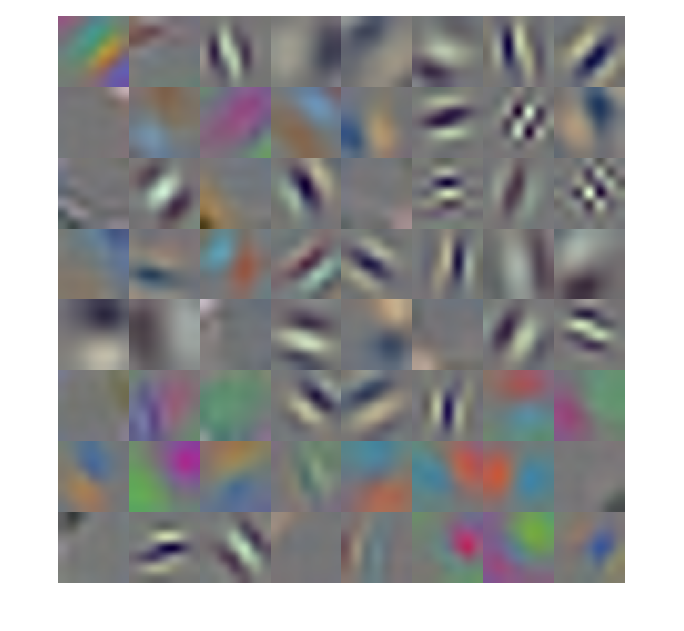

W = net.Layers(2).Weights;
montage(rescale(W))

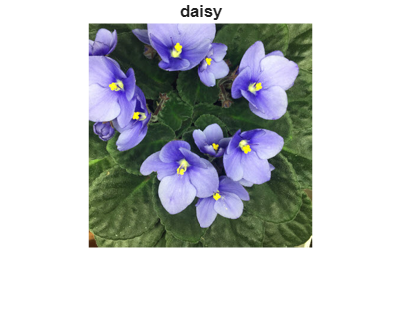

im = imread("violet.jpg");
im = imresize(im,inputSize(1:2));
imshow(im)
title(scores2label(minibatchpredict(net,im),classes))

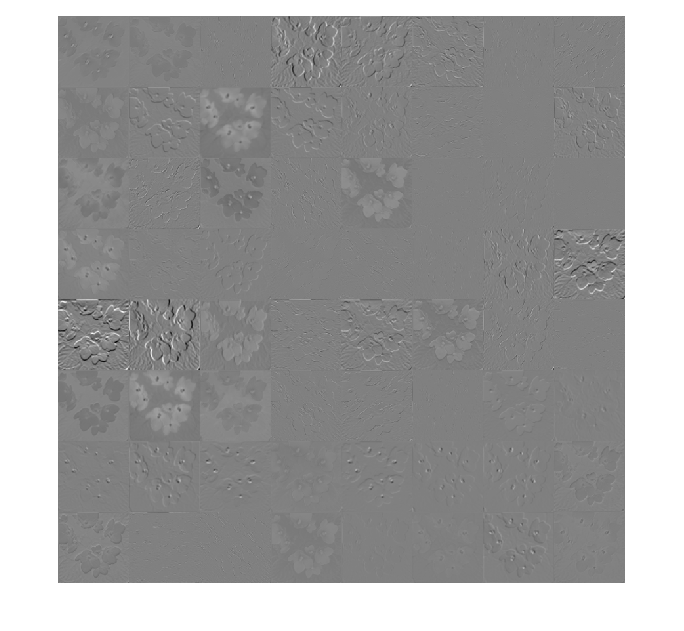

actvn = minibatchpredict(net,im,Outputs=net.Layers(2).Name);
montage(mat2gray(actvn))

net.Layers

ans =   143×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   2-D Convolution               64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               2-D Convolution               64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      2-D Convolution           

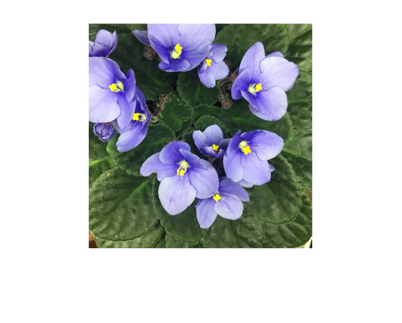

imshow(im)

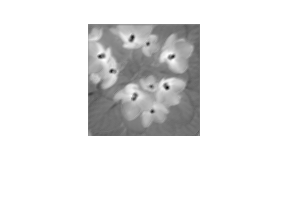

avtvn=minibatchpredict(net,im,Outputs="conv1-7x7_s2");
imshow(rescale(avtvn(:,:,11)))

[actvnEarly actvnLate] = minibatchpredict(net,im,Outputs=["conv1-7x7_s2" "conv2-3x3"])

actvnEarly = 112×112×64 single array
actvnEarly(:,:,1) =

    3.3550   20.0717   15.2370   13.6265   12.3042   14.7061   11.9640    3.3721    8.8134   14.3405    7.6536   24.1508   20.8770   16.0823   13.3056    1.7430    5.5948   -0.2447   10.0378    5.4013    8.2178   14.5887    7.0022   24.3472   21.7709   19.4005   15.4391    8.2437   56.8951  -13.4125  -59.7266  -54.1502  -61.1804  -66.8680  -65.6414  -68.1839  -69.3563  -67.6322  -62.9733  -59.9336  -50.7314  -55.3577  -44.5568  -55.5894  -83.8548  -44.2316  -38.3878  -34.5345  -35.0022  -29.0234  -39.2099  -40.9722  -44.6369  -42.8475  -39.4459  -31.8951  -34.3254  -42.0849  -48.7719  -42.8444  -53.7042  -65.0167  -69.1351  -78.3939   -7.1492   -6.0043  -12.6539  -11.6193  -37.8076  -35.3254   -3.9068   21.4217   19.0736    6.6128    7.9078   11.2824    7.9780   11.7003    3.7126   -3.6448    3.3278    6.1990    5.7245   10.1662   12.2068   16.1895   17.7045    8.5634    6.9496    2.9739   15.6665   18.4261   22.6384   10.0164  

actvnLate = 56×56×192 single array
actvnLate(:,:,1) =

  -24.5228  -73.2426  -96.5558 -123.6498  -92.2441  -52.7482  -50.1541  -62.1930  -47.5368  -43.6360  -49.9931  -71.5441 -112.6276  -89.9627  -76.3874 -101.6040 -131.3733 -134.3771 -140.7888 -157.3101 -185.8011 -172.2289 -181.9348 -187.2933 -178.4008 -188.3708 -189.6099 -180.5684 -161.1991 -156.6548 -130.2626  -81.6173  -58.6061  -68.1416  -68.6652  -82.5496  -78.4155  -69.9698  -84.7967  -97.9053  -71.0720  -85.1544  -84.7534  -56.4478  -58.4186  -90.8071  -92.3531  -82.7884  -82.5252 -103.7518 -120.4151 -114.2588 -100.8000  -99.6341 -120.2196 -110.3263
  -38.7323  -86.6828 -132.0925 -162.0226 -110.7644  -81.8845  -54.1780  -52.7909  -40.3980  -29.6989  -45.6230  -49.3461 -107.3404 -142.1555 -152.5917 -159.5831 -135.4186  -91.1275 -107.5061 -130.5200 -135.9502 -121.2785  -93.6556 -109.9347 -110.5115 -109.7940 -100.4771  -91.3258  -85.9299  -93.3369  -78.3844  -19.0228  -13.8974  -61.6708  -75.5181  -64.6317  -44.4870  -57.1183  -8

montage(mat2gray(actvnEarly))

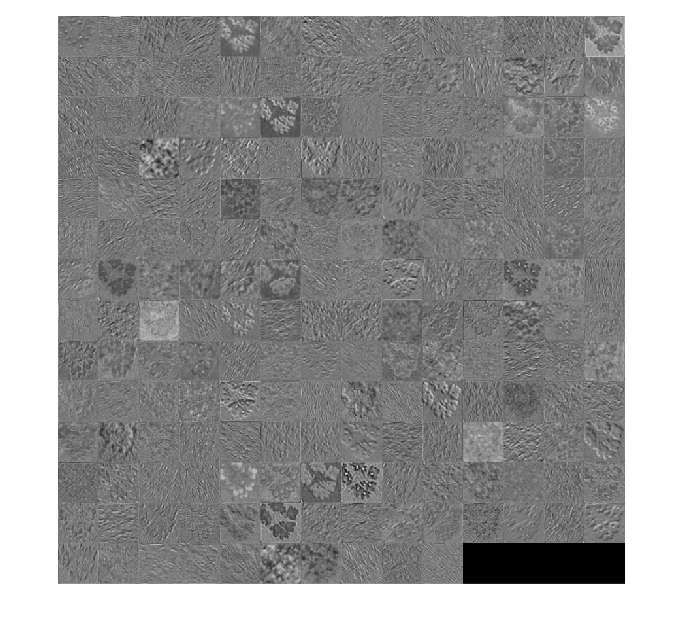

montage(mat2gray(actvnLate))

analyzeNetwork(net)